close all
clear
clc

定义仿真时间

t = [0:.1:40]';

准备绘图，先从左上角第一个子图开始

figure, id = 1;

取遍所有的角频率omega = 0.5，0.25，0

for omega = .5:-.25:0

取遍所有的实部sigma = -0.06, -0.03, ..., 0.06

    for sigma = -.06:.03:.06

构造一个极点p，如果p不在实轴上，则应构造一对共轭极点

        p = sigma + 1i*omega;
        if omega ~= 0
            p = [p];
        end

用该极点或共轭极点生成一个系统的传递函数

        [b,a] = zp2tf([],p,1);

在第id个子图上绘制冲激响应，id加一

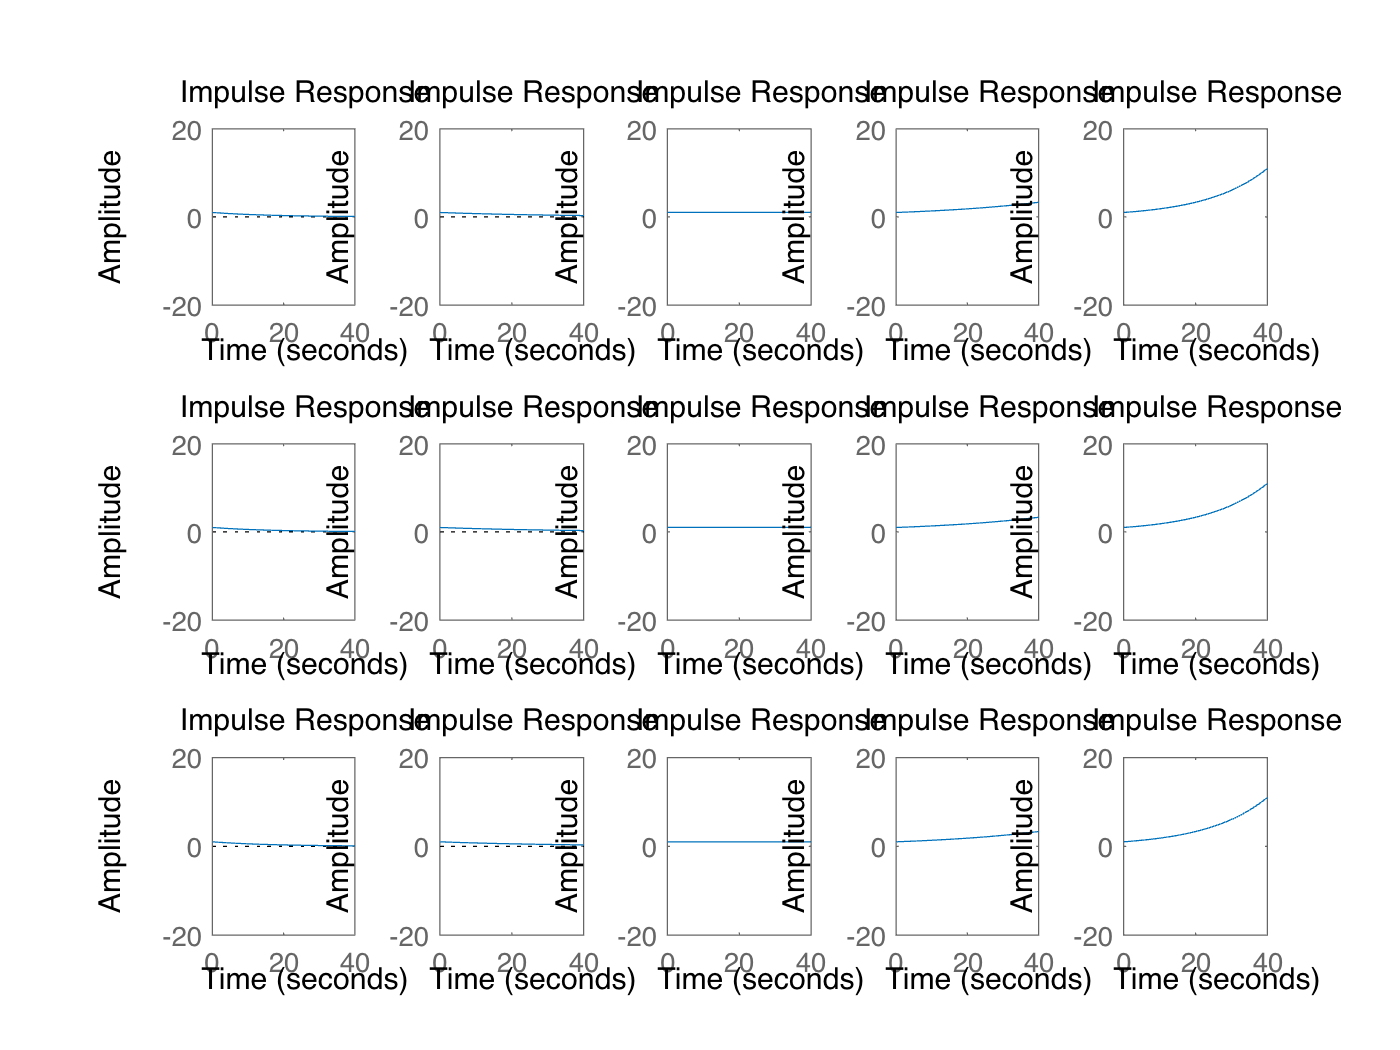

        subplot(3,5,id);
        impulse(b,a,t);
        set(gca,'YLim',[-20,20]);
        id = id + 1;
    end
end